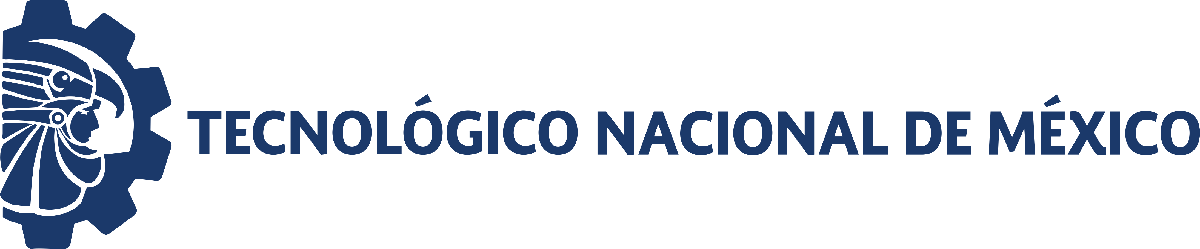                                 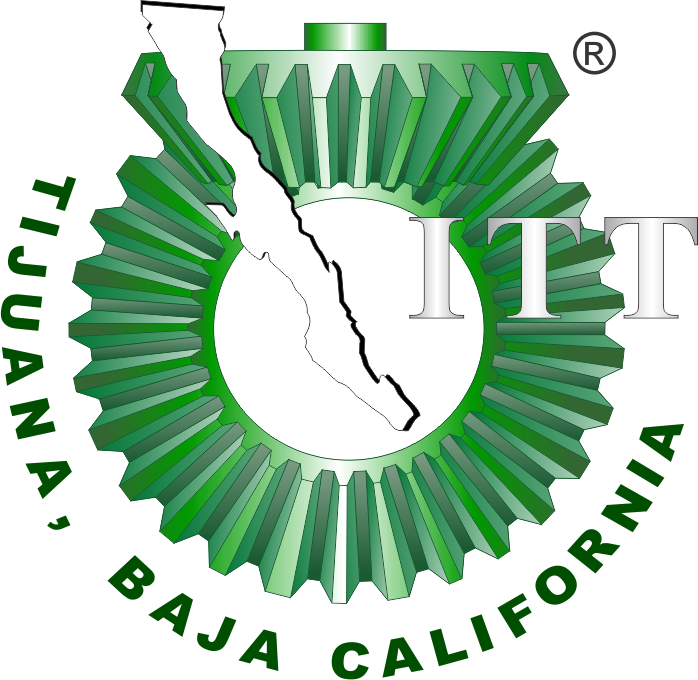

# Práctica uno: Diseño de controladores para un sistema de segundo orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

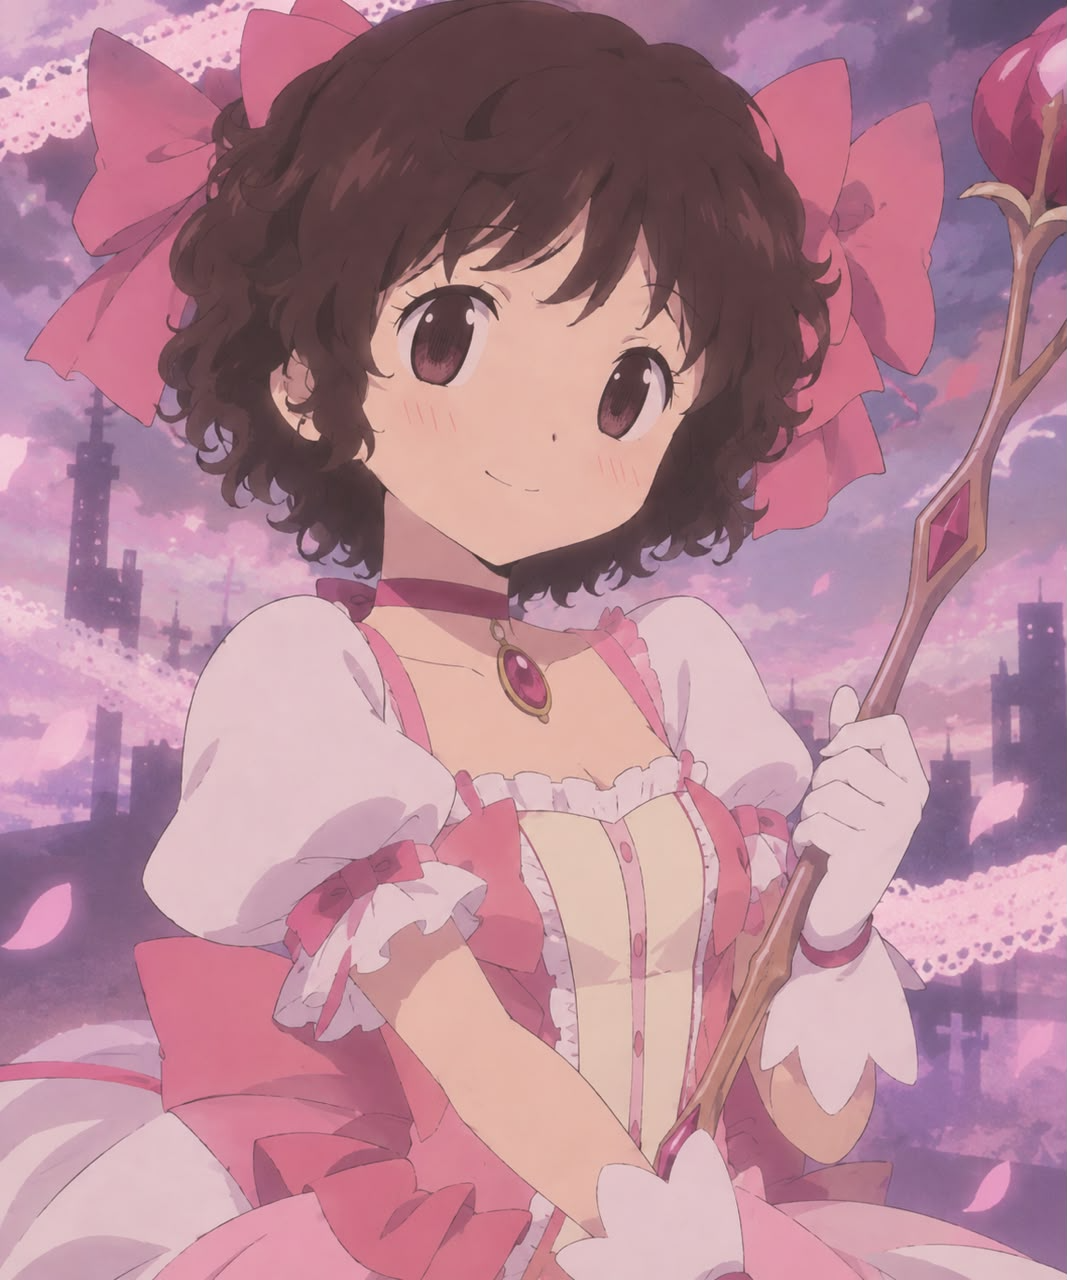

Nombre del alumno: **Nicole Arredondo Arevalo**

Número de control: 23212179

Correo institucional: L23212179**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema1')
parameters.StopTime = '10'

parameters = struct with fields:
    StopTime: '10'


parameters.Solver = 'ode15s'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'


parameters.MaxStep = '1e-3'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'
     MaxStep: '1e-3'


% set_param('sistema/Vs(t): CE/Vs','VectorFormat','1-D array');

## Respuesta al escalón

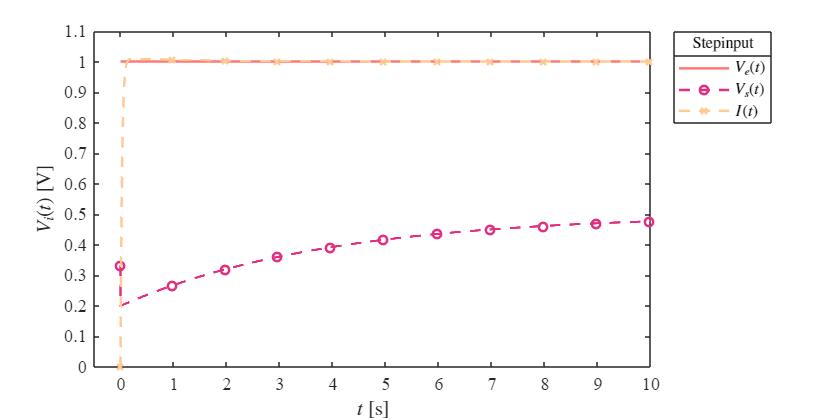

set_param('sistema1/S1','sw','1')
set_param('sistema1/Ve(t)','sw','1')
x1 = sim('sistema1',parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.I,'Step')

## Respuesta al impulso

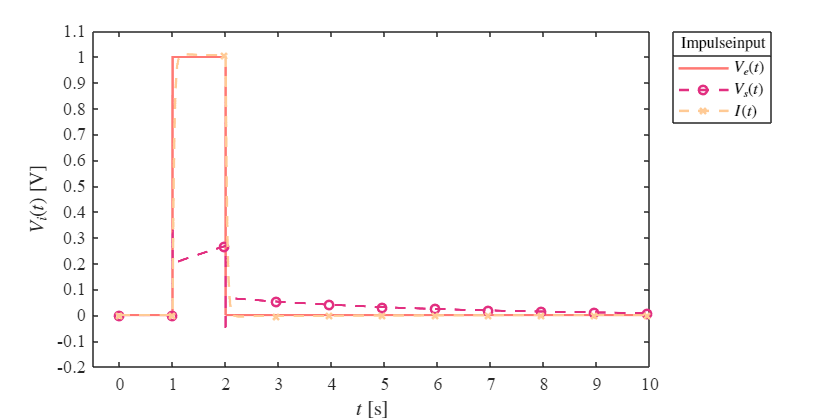

set_param('sistema1/S1','sw','0')
set_param('sistema1/Ve(t)','sw','1')
x2 = sim('sistema1',parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.I,'Impulse')

## Respuesta a la rampa

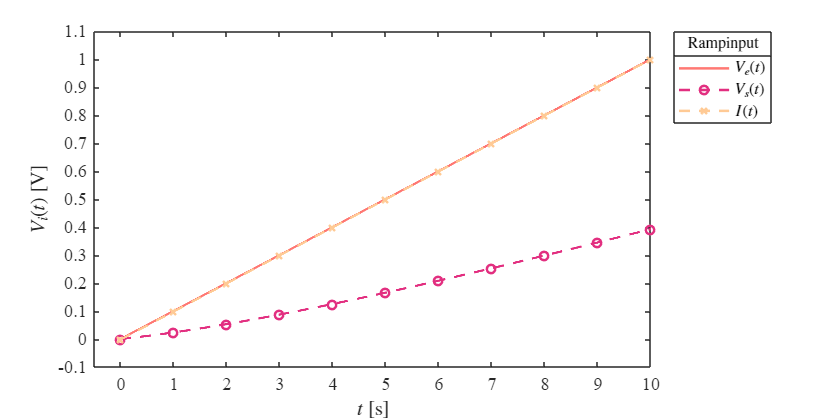

set_param('sistema1/S2','sw','1')
set_param('sistema1/Ve(t)','sw','0')
x3 = sim('sistema1',parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.I,'Ramp')

## Respuesta a la función sinusoidal

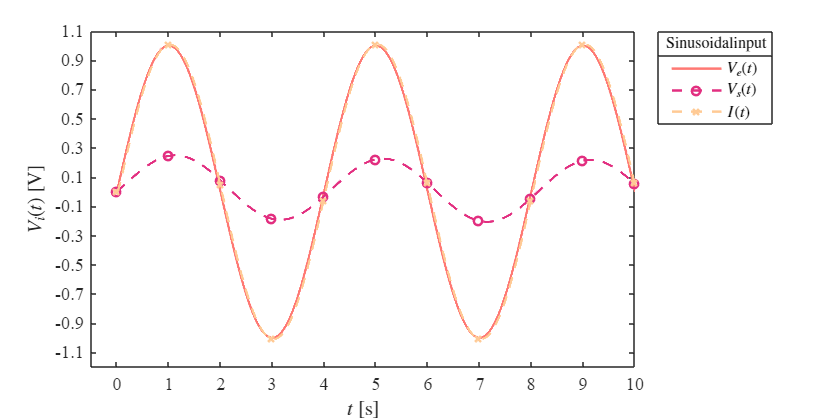

set_param('sistema1/S2','sw','0')
set_param('sistema1/Ve(t)','sw','0')
x4 = sim('sistema1',parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.I,'Sinusoidal')

## **Funcion: Respuestas de la simulacion **

function plotsignals(t,Ve,Vs,I,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [255, 120, 115]/255;
    clr2 = [226, 47, 128]/255;
    clr3 = [255, 202, 149]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot(t,Ve,'-',t,Vs,'--o',t,I,'--x','LineWidth',1.5,'MarkerSize',...
        5,'MarkerIndices',1:1e3:length(t));
    L = legend('$V_{e}(t)$','$V_s(t)$','$I(t)$');
    set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
    title(L,[signal,'input'])
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')

    xlim([-0.5 10]); xticks(0:1:10)
    if signal == "Step"
        ylim([0 1.1]); yticks(0:0.1:1.1)
    elseif signal == "Impulse"
        ylim([-0.2 1.1]); yticks(-0.2:0.1:1.1)
    elseif signal == "Ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    elseif signal == "Sinusoidal"
        ylim([-1.2 1.1]); yticks(-1.1:0.2:1.1)
    end

    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end